# MA 423 Matrix Computations                    Lab - 4

## Name: Rasesh Srivastava

## Roll number: 210123072

format long e

## Question 1

(4/3 - 1) * 3 - 1

ans =     -2.220446049250313e-16


**Expected Result:** Ideally, this expression should yield 0 because 4/3 − 1  should give 1/3, and multiplying by 3 gives 1, which when subtracted by 1 results in 0.

**Reason for Anomaly:** Due to the finite precision of floating-point arithmetic, 4/3 is represented with a slight error. When subtracting 1 from this approximation, the small error is magnified in the final calculation, resulting in a very small but non-zero value.

5 * ((1 + exp(-50)) - 1) / ((1 + exp(-50)) - 1)

ans =    NaN


**Expected Result:** The expression should evaluate to 5, since the numerator and denominator are identical and should cancel out.

**Reason for Anomaly:** exp (−50) is an extremely small number, so 1 + exp (−50) is approximately equal to 1. This makes the numerator and denominator nearly zero, leading to a division of 0 by 0, which is undefined and results in NaN (Not a Number).

log(exp(750)) / 100

ans =    Inf


**Expected Result:** exp (750) is a very large number, but taking the logarithm should return 750, and dividing by 100 should yield 7.5.

**Reason for Anomaly:** exp (750) exceeds the maximum value that can be represented in floating-point arithmetic, resulting in an overflow. When an overflow occurs, the result is typically represented as infinity (Inf).

These anomalies highlight how numerical computations can produce unexpected results due to the inherent limitations of how numbers are represented and manipulated in computers using finite precision systems.

## Question 2

#### (i) function

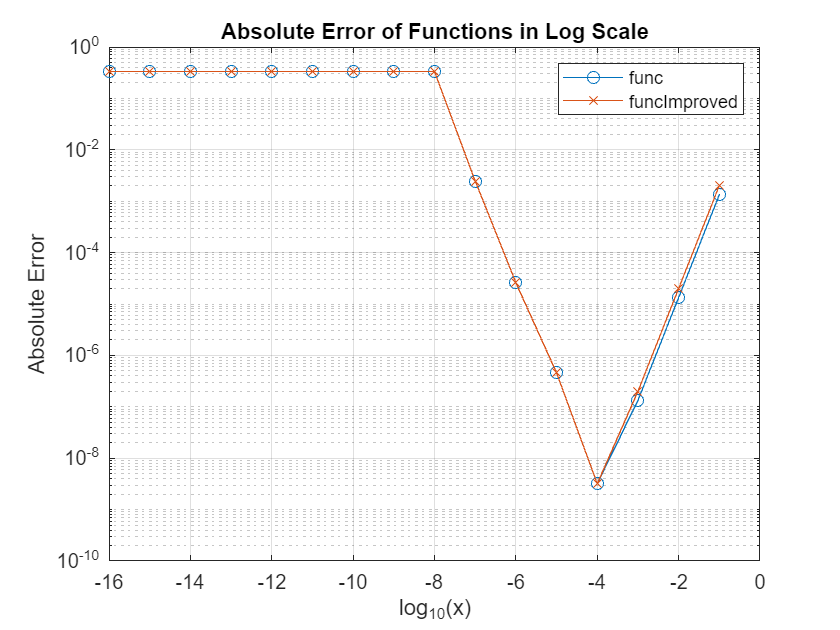

p = 1:16;
xVals = 10.^(-p);

m = @(x) (tan(x)-x)./x.^3;
fImproved = @(x) (x + x.^3 / 3 + x.^5 / 5 + x.^7 / 7 - x) ./ x.^3;
exactF = 1/3;

func = m;
xValue = xVals;
exactFunc = exactF;
funcImproved = fImproved;

funcVals = func(xValue);
absErrorFunc = abs(funcVals - exactFunc);
numSigDigitsFunc = -log10(max(absErrorFunc, eps));
smallestP = find(numSigDigitsFunc <= 0, 1);
if isempty(smallestP)
    smallestP = NaN;
end

funcImprovedVals = funcImproved(xValue);
absErrorFuncImproved = abs(funcImprovedVals - exactFunc);
numSigDigitsFuncImproved = -log10(max(absErrorFuncImproved, eps));
smallestPImproved = find(numSigDigitsFuncImproved <= 0, 1);
if isempty(smallestPImproved)
    smallestPImproved = NaN;
end

figure;
semilogy(log10(xValue), absErrorFunc, '-o', 'DisplayName', 'func');
hold on;
semilogy(log10(xValue), absErrorFuncImproved, '-x', 'DisplayName', 'funcImproved');
xlabel('log_{10}(x)');
ylabel('Absolute Error');
legend('show');
grid on;
title('Absolute Error of Functions in Log Scale');
hold off;

fprintf('Smallest P for original function: %d\n', smallestP);

Smallest P for original function: NaN


fprintf('Smallest P for improved function: %d\n', smallestPImproved);

Smallest P for improved function: NaN


#### (ii) function

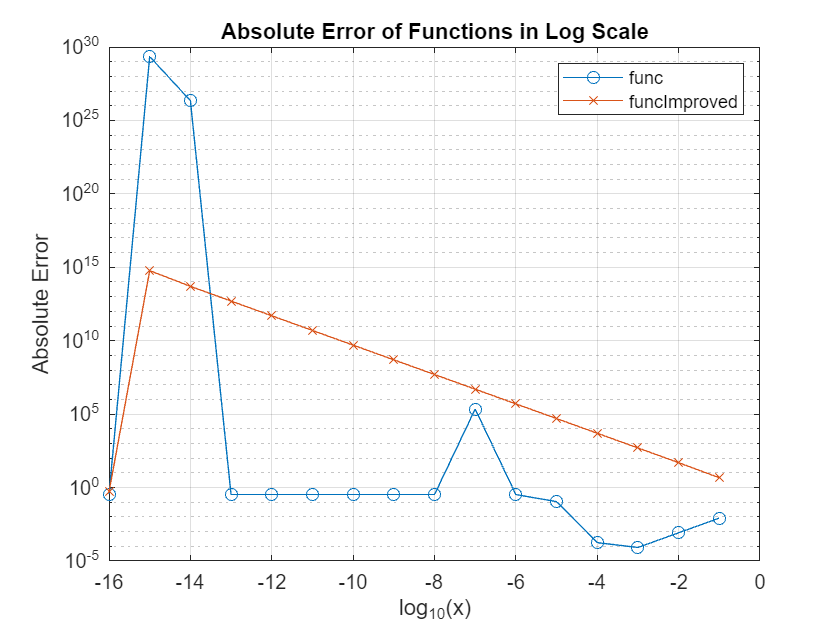

p = 1:16;
xVals = 10.^(-p);

g = @(x) (exp(x) + cos(x) - sin(x) - 2)./x.^3;
gImproved = @(x) (x + x.^2 / 2 + x.^3 / 6 - x - x.^3 / 6) ./ x.^3;
exactG = 1/3;

func = g;
xValue = xVals;
exactFunc = exactG;
funcImproved = gImproved;

funcVals = func(xValue);
absErrorFunc = abs(funcVals - exactFunc);
numSigDigitsFunc = -log10(max(absErrorFunc, eps));
smallestP = find(numSigDigitsFunc <= 0, 1);
if isempty(smallestP)
    smallestP = NaN;
end

funcImprovedVals = funcImproved(xValue);
absErrorFuncImproved = abs(funcImprovedVals - exactFunc);
numSigDigitsFuncImproved = -log10(max(absErrorFuncImproved, eps));
smallestPImproved = find(numSigDigitsFuncImproved <= 0, 1);
if isempty(smallestPImproved)
    smallestPImproved = NaN;
end

figure;
semilogy(log10(xValue), absErrorFunc, '-o', 'DisplayName', 'func');
hold on;
semilogy(log10(xValue), absErrorFuncImproved, '-x', 'DisplayName', 'funcImproved');
xlabel('log_{10}(x)');
ylabel('Absolute Error');
legend('show');
grid on;
title('Absolute Error of Functions in Log Scale');
hold off;

fprintf('Smallest P for original function: %d\n', smallestP);

Smallest P for original function: 7


fprintf('Smallest P for improved function: %d\n', smallestPImproved);

Smallest P for improved function: 1


#### (iii) function

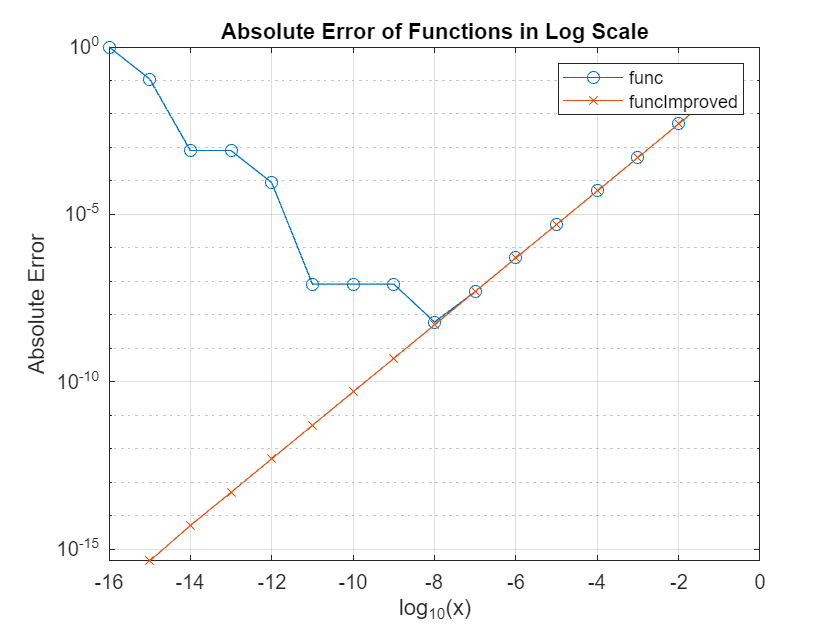

p = 1:16;
xVals = 10.^(-p);

h = @(x) (exp(x)-1)./x;
hImproved = @(x) (x + x.^2 / 2 + x.^3 / 6 + x.^4 / 24 - x) ./ x;
hImproved = @(x) 1 + x/2 + x.^2/6 + x.^3/24 + x.^4/120;
exactH = 1;

func = h;
xValue = xVals;
exactFunc = exactH;
funcImproved = hImproved;

funcVals = func(xValue);
absErrorFunc = abs(funcVals - exactFunc);
numSigDigitsFunc = -log10(max(absErrorFunc, eps));
smallestP = find(numSigDigitsFunc <= 0, 1);
if isempty(smallestP)
    smallestP = NaN;
end

funcImprovedVals = funcImproved(xValue);
absErrorFuncImproved = abs(funcImprovedVals - exactFunc);
numSigDigitsFuncImproved = -log10(max(absErrorFuncImproved, eps));
smallestPImproved = find(numSigDigitsFuncImproved <= 0, 1);
if isempty(smallestPImproved)
    smallestPImproved = NaN;
end

figure;
semilogy(log10(xValue), absErrorFunc, '-o', 'DisplayName', 'func');
hold on;
semilogy(log10(xValue), absErrorFuncImproved, '-x', 'DisplayName', 'funcImproved');
xlabel('log_{10}(x)');
ylabel('Absolute Error');
legend('show');
grid on;
title('Absolute Error of Functions in Log Scale');
hold off;

fprintf('Smallest P for original function: %d\n', smallestP);

Smallest P for original function: 16


fprintf('Smallest P for improved function: %d\n', smallestPImproved);

Smallest P for improved function: NaN


## Question 3

#### Part (a)

Example f(x) = (x - 4) .^ 2

p = [1 -8 16];

Example of evaluation at a Scalar Value

x = 9;

Calculated using Horner's method:

Horner(p, x)

ans =     25


Calculated using exact formula:

f(x)

ans =     25


Example of evaluation at a Vector Value

x = [4, 7, 2];

Calculated using Horner's method:

Horner(p, x)

ans =      0     9     4


Calculated using exact formula:

f(x)

ans =      0     9     4


#### Part (b)

p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];
a = [1.95, 1.96, 1.97, 1.98, 1.99, 1.96];
b = [2.05, 2.04, 2.03, 2.02, 2.01, 1.99];

for i = 1 : length(a)
    if i == 1
        fprintf('The root of the polynomial for different intervals are as follows:\n');
    end
    tol = 1e-8;
    x0 = a(i);
    x1 = b(i);
    x = bisect(p, x0, x1, tol);
    fprintf('Computed Root of p(x) for root in [%f, %f] = ', a(i), b(i));
    disp(x);
end

The root of the polynomial for different intervals are as follows:


Computed Root of p(x) for root in [1.950000, 2.050000] = 

     2.049971765279770e+00



Computed Root of p(x) for root in [1.960000, 2.040000] = 

     2.023957281112672e+00



Computed Root of p(x) for root in [1.970000, 2.030000] = 

     2.021199414730072e+00



Computed Root of p(x) for root in [1.980000, 2.020000] = 

     2.012653608322144e+00



Computed Root of p(x) for root in [1.990000, 2.010000] = 

     2.006189680099487e+00



Computed Root of p(x) for root in [1.960000, 1.990000] = 

     1.972823069095611e+00



### Observations:

We observe that the root of polynomial is not exactly 2, but there is a variation in it, and as the interval size is made smaller, the absolute difference between the computed root and the exact root decreases. This can be attributed to the limitations of finite precision arithmetic and the rounding errors caused while evaluation of polynomial using Horner’s method. As a result, the computed roots are in the neighbourhood of 2 and not exactly 2. Also we can see that for the last interval even though the interval does not contain 2, we are getting some solution around 2.

#### Part (c)

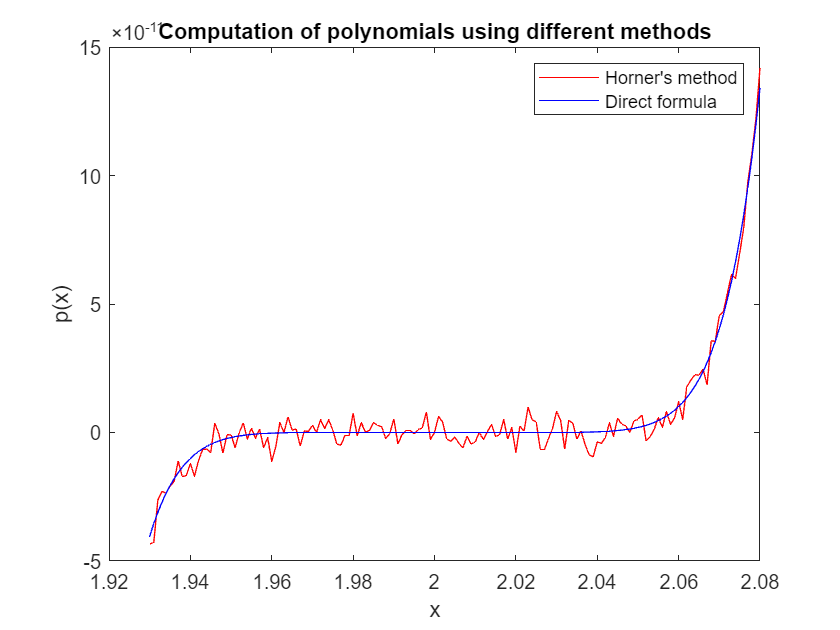

x_min = 1.93;
x_max = 2.08;
x = linspace(x_min, x_max, 151);

p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];
y_horner = Horner(p, x);

y_direct = (x - 2) .^ 9;

plot(x, y_horner, 'red');
hold on;
plot(x, y_direct, 'blue');
hold off;

xlabel('x');
ylabel('p(x)');
title('Computation of polynomials using different methods');
legend({'Horner''s method', 'Direct formula'});

We can observe that the plots corresponding to the Horner's method and the direct formula do not exactly coincide and they differ from one another. The plot for the Horner's method crosses x-axis multiple times and there is a large number of small variations around this line.

The possible reasons for this behaviour is the rounding errors committed while evaluation of polynomial p(x) using Horner’s method and the limitations of the finite precision systems.

The small rounding errors are causing the values of p(x) to fluctuate around x = 2 particularly. Small negative values are pushed to negative values, while small positive values are pushed to negative numbers in the neighbourhood of 2. Due to this, the graph crosses x-axis in multiple places apart from 2 computationally. Theoretically, we only have 2 as root with its multiplicity being 9, while computationally we have roots in neighbourhood of 2 (some even in intervals around 2, but not containing 2).

Also, there is possibility of catastrophic cancellation happening in Horner’s method due to the involvement of multiplication and addition at each step of the computation. So, catastrophic cancellation is a possible reason for the plots to differ from one another.

# Function Programs

## Question 3

#### Part (a)

function y = Horner(p, x)
    n = length(p);
    y = zeros(size(x));
    
    for i = 1 : n
        y = p(i) + x .* y;
    end
end

Example Function

function y = f(x)
    y = (x - 4) .^ 2;
end

#### Part (b)

function x = bisect(p, x0, x1, tol)
    x = (x0 + x1) / 2;
    while x1 - x0 > 2*tol
        [a, b, c] = deal(Horner(p, x0), Horner(p, x), Horner(p, x1));
                
        if a * b < 0
            x1 = x;
        else
            x0 = x;
        end
        
        x = (x0 + x1) / 2;
    end
end